%% Identificação ARX para Sistema de Primeira Ordem
% Autor: [Seu Nome]
% Descrição: Identificação de modelo ARX para FT 0.02/(791s + 1) com Kp=180, Ki=0.18

close all; clear; clc;

%% 1. Definição da Função de Transferência Contínua e Discretização
G_cont = tf(0.02, [791 1]);  % FT contínua: 0.02 / (791s + 1)
Ts = 1;  % Período de amostragem
G_disc = c2d(G_cont, Ts, 'zoh');  % Discretização com ZOH
[numd, dend] = tfdata(G_disc, 'v');  % Coeficientes do numerador e denominador

% Exibição da FT discreta
disp('Função de Transferência Discreta:');

Função de Transferência Discreta:


disp(G_disc);

  tf with properties:

       Numerator: {[0 2.5268e-05]}
     Denominator: {[1 -0.9987]}
        Variable: 'z'
         IODelay: [0]
      InputDelay: [0]
     OutputDelay: [0]
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: [1]
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




%% 2. Controlador PI Discreto (Kp = 180, Ki = 0.18)
Kp = 180;
Ki = 0.18;
C_cont = tf([Kp Ki], [1 0]);  % Controlador PI contínuo
C_disc = c2d(C_cont, Ts, 'tustin');  % Discretização com Tustin
[numc, denc] = tfdata(C_disc, 'v');

% Exibição do controlador PI discreto
disp('Controlador PI Discreto:');

Controlador PI Discreto:


disp(C_disc);

  tf with properties:

       Numerator: {[180.0900 -179.9100]}
     Denominator: {[1 -1]}
        Variable: 'z'
         IODelay: [0]
      InputDelay: [0]
     OutputDelay: [0]
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: [1]
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



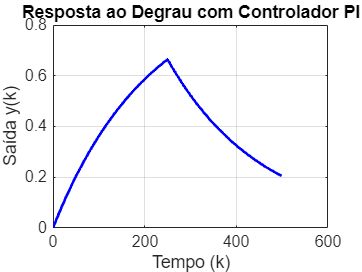


%% 3. Simulação da Malha Fechada
N = 500;  % Número de amostras
t = (0:N-1)*Ts;  % Vetor de tempo

% Sinal de entrada (degrau + ruído)
u = [ones(N/2,1); zeros(N/2,1)] + 0.01*randn(N,1);

% Resposta da malha fechada
sys_cl = feedback(G_disc*C_disc, 1);  % Malha fechada
y = lsim(sys_cl, u, t);  % Simulação

% Plot da resposta
figure(1)
plot(t, y, 'b', 'LineWidth', 2);
set(gca, 'FontSize', 12)
xlabel('Tempo (k)');
ylabel('Saída y(k)');
title('Resposta ao Degrau com Controlador PI');
grid on;

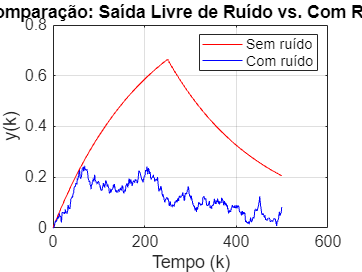


%% 4. Geração de Dados para Identificação (com ruído)
y_noisy = zeros(N,1);
y_noisy(1) = 0;
for k = 2:N
    y_noisy(k) = -dend(2)*y_noisy(k-1) + numd(1)*u(k-1) + 0.01*randn;
end

% Plot comparativo
figure(2)
plot(t, y, 'r', t, y_noisy, 'b');
legend('Sem ruído', 'Com ruído');
set(gca, 'FontSize', 12)
xlabel('Tempo (k)');
ylabel('y(k)');
title('Comparação: Saída Livre de Ruído vs. Com Ruído');
grid on;


%% 5. Identificação ARX para Primeira Ordem
na = 1;  % 1 atraso na saída (y(k-1))
nb = 1;  % 1 atraso na entrada (u(k-1))
nk = 1;  % Tempo morto

% Construção da matriz de regressores
phi_arx = [];
Y_arx = [];
for k = max(na,nb+nk)+1:N
    phi_k = [-y_noisy(k-1); u(k-nk)];  % -y(k-1) e u(k-1)
    phi_arx = [phi_arx; phi_k'];
    Y_arx = [Y_arx; y_noisy(k)];
end

% Estimação dos parâmetros
theta_arx = pinv(phi_arx)*Y_arx;
a1 = theta_arx(1);
b1 = theta_arx(2);

disp('Parâmetros ARX identificados:');

Parâmetros ARX identificados:


disp(['a1 = ', num2str(a1)]);

a1 = -0.9855


disp(['b1 = ', num2str(b1)]);

b1 = 0.0027104


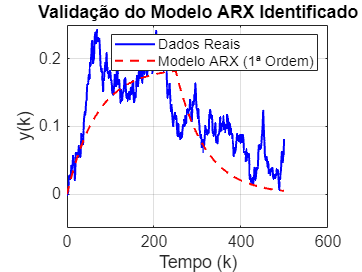


% Validação: Simulação com modelo identificado
y_arx = zeros(N,1);
y_arx(1) = 0;
for k = 2:N
    y_arx(k) = -a1*y_arx(k-1) + b1*u(k-1);
end

% Plot de validação
figure(3)
plot(t, y_noisy, 'b', t, y_arx, 'r--', 'LineWidth', 1.5);
legend('Dados Reais', 'Modelo ARX (1ª Ordem)');
set(gca, 'FontSize', 12)
xlabel('Tempo (k)');
ylabel('y(k)');
title('Validação do Modelo ARX Identificado');
grid on;

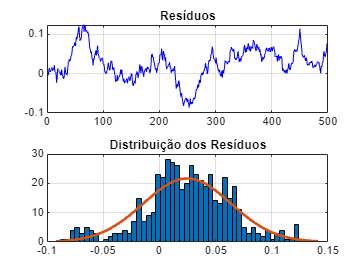


%% 6. Análise de Resíduos
residuos = y_noisy(max(na,nb+nk)+1:N) - y_arx(max(na,nb+nk)+1:N);

figure(4)
subplot(2,1,1)
plot(residuos, 'b');
title('Resíduos');
grid on;

subplot(2,1,2)
histfit(residuos, 50);
title('Distribuição dos Resíduos');
grid on;


%% Função ZOH (Seguidor de Ordem Zero)
function y = zoh(x, T)
    y = [];
    for k = 1:length(x)
        y = [y; ones(T,1)*x(k)];
    end
end
%% 7. Equação ARX no Formato Geral (para LaTeX / Overleaf)
fprintf('\n--- Equação ARX de Primeira Ordem (Formato Geral) ---\n');


--- Equação ARX de Primeira Ordem (Formato Geral) ---


fprintf('y(k) = -a_1*y(k-1) + b_1*u(k-1)\n');

y(k) = -a_1*y(k-1) + b_1*u(k-1)


fprintf('a_1 = %.6f\n', a1);

a_1 = -0.985496


fprintf('b_1 = %.6f\n', b1);

b_1 = 0.002710



% Geração automática do código LaTeX
fprintf('\nCopie e cole no Overleaf:\n');


Copie e cole no Overleaf:


fprintf('\\begin{equation}\n');

\begin{equation}


fprintf('\\hat{y}(k) = %.4f \\cdot y(k-1) + %.4f \\cdot u(k-1)\n', -a1, b1);

\hat{y}(k) = 0.9855 \cdot y(k-1) + 0.0027 \cdot u(k-1)


fprintf('\\end{equation}\n');

\end{equation}
